Nodes scaling is fixed


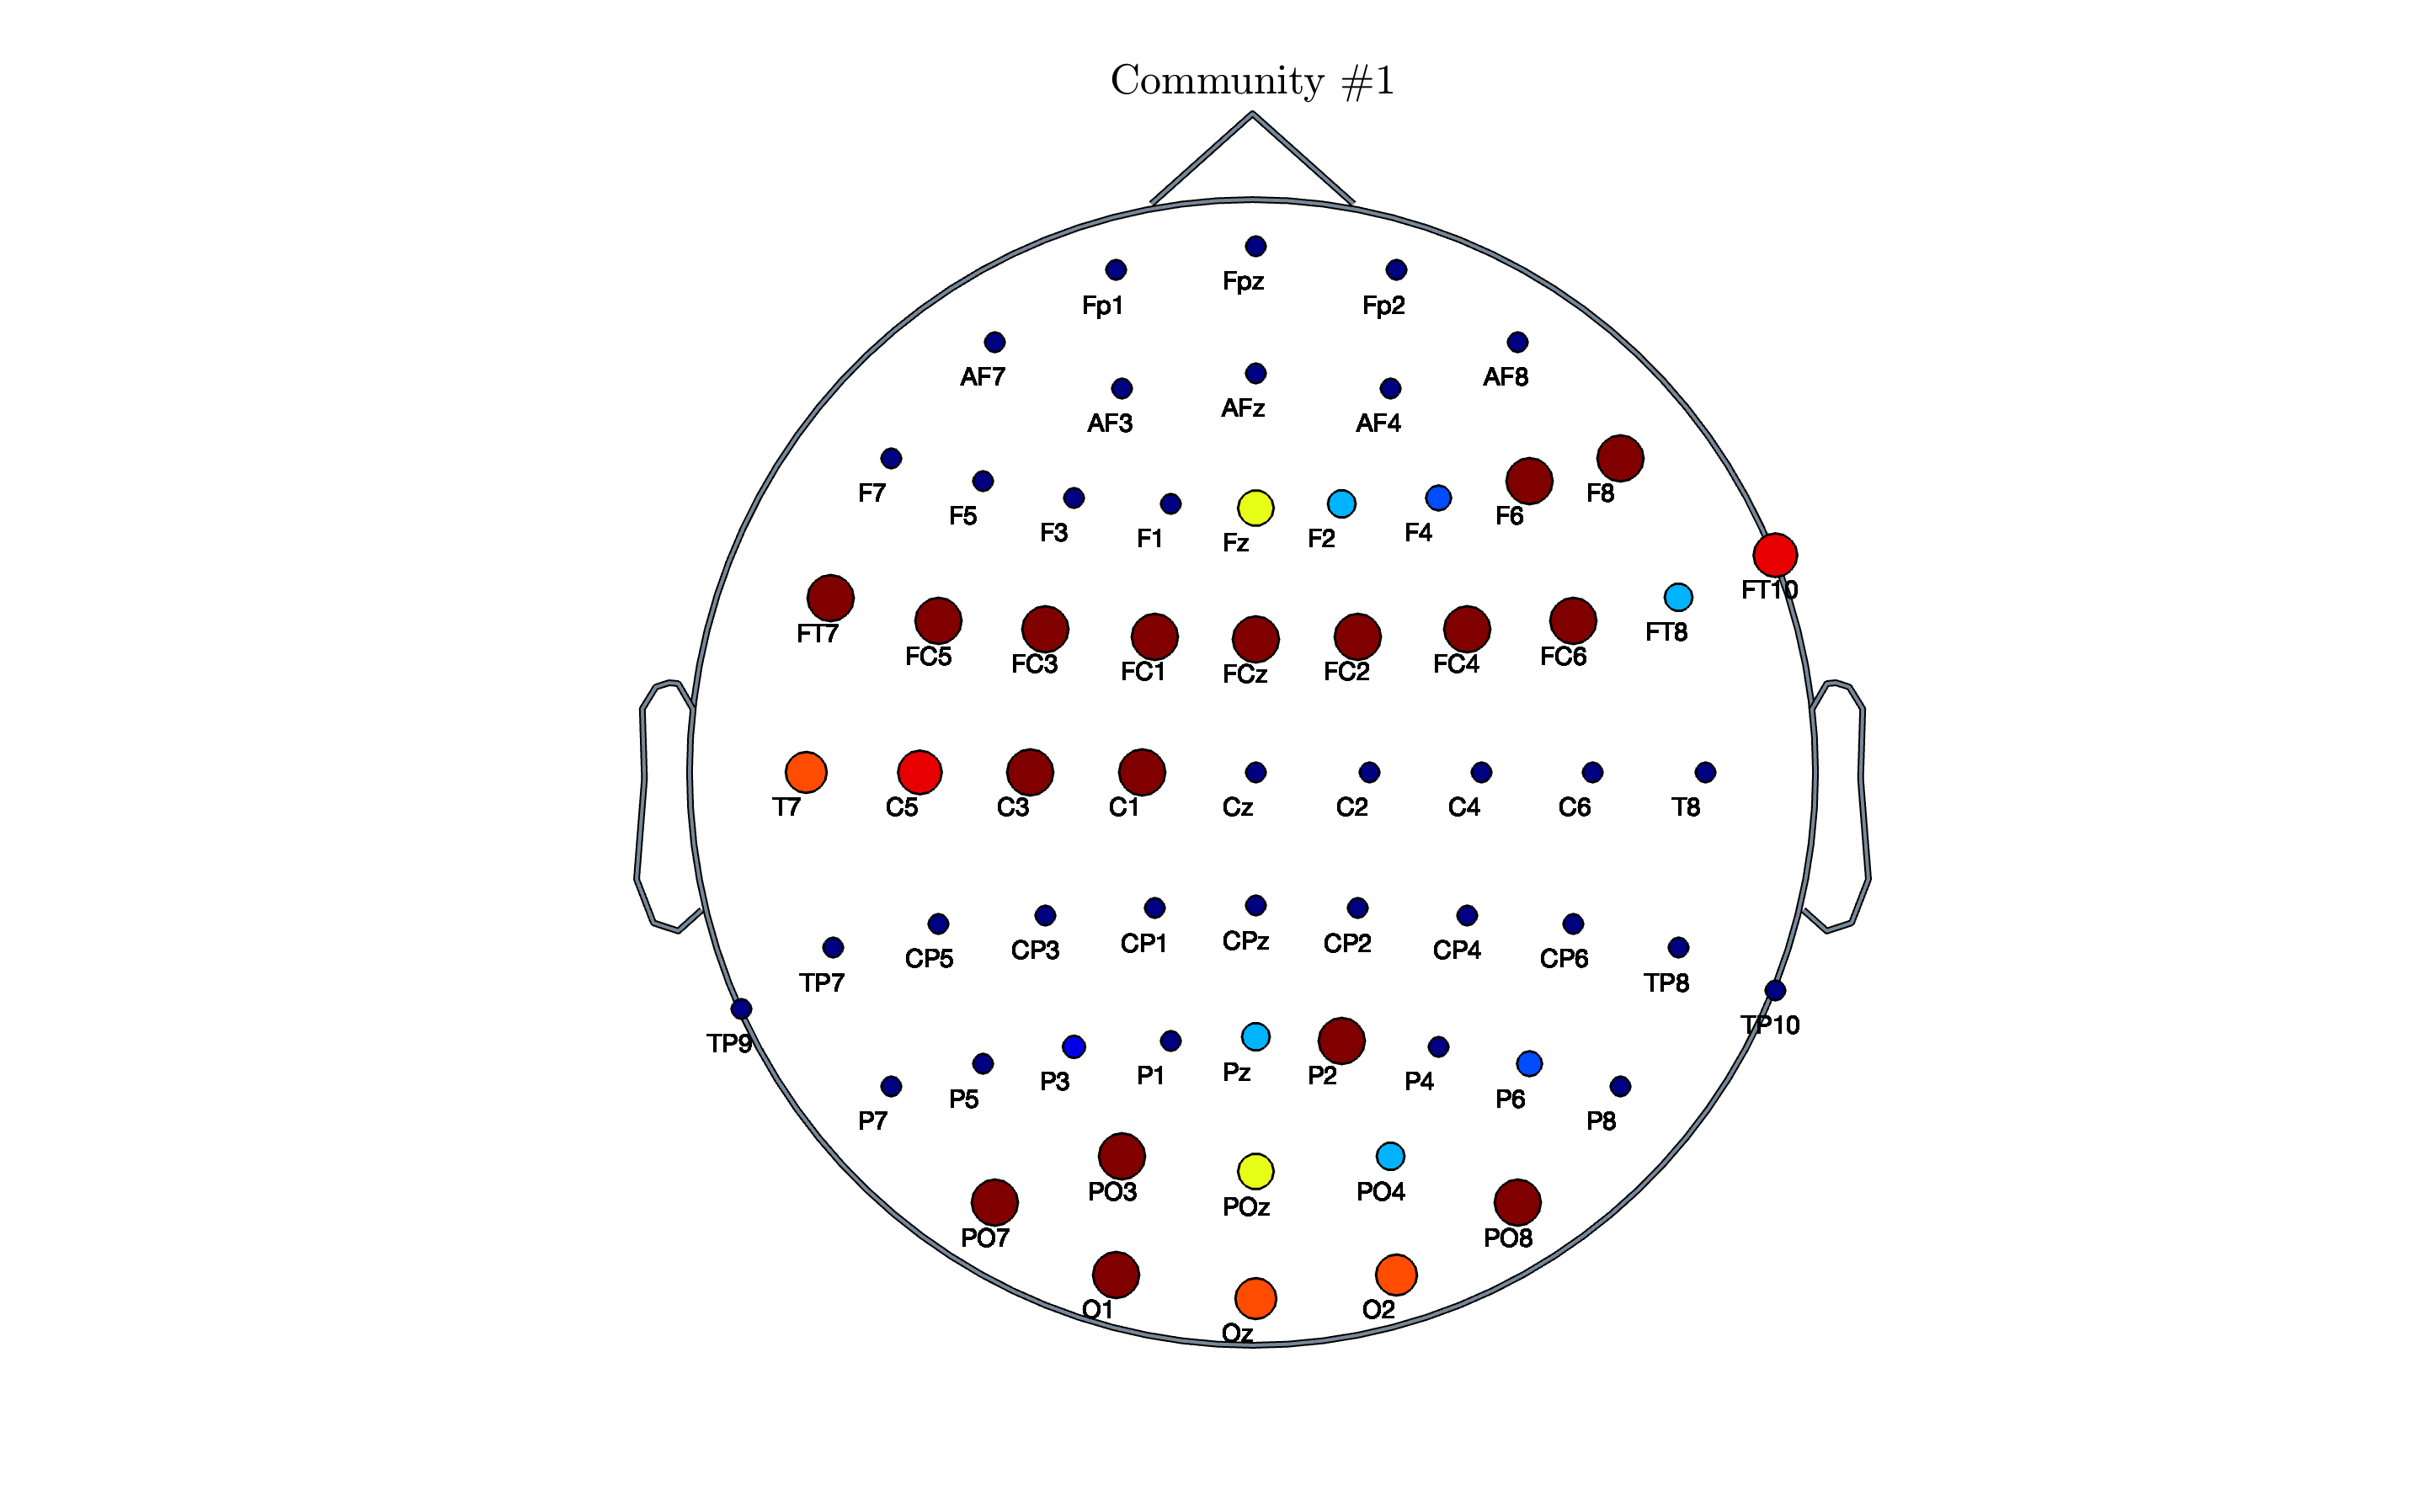

Nodes scaling is fixed


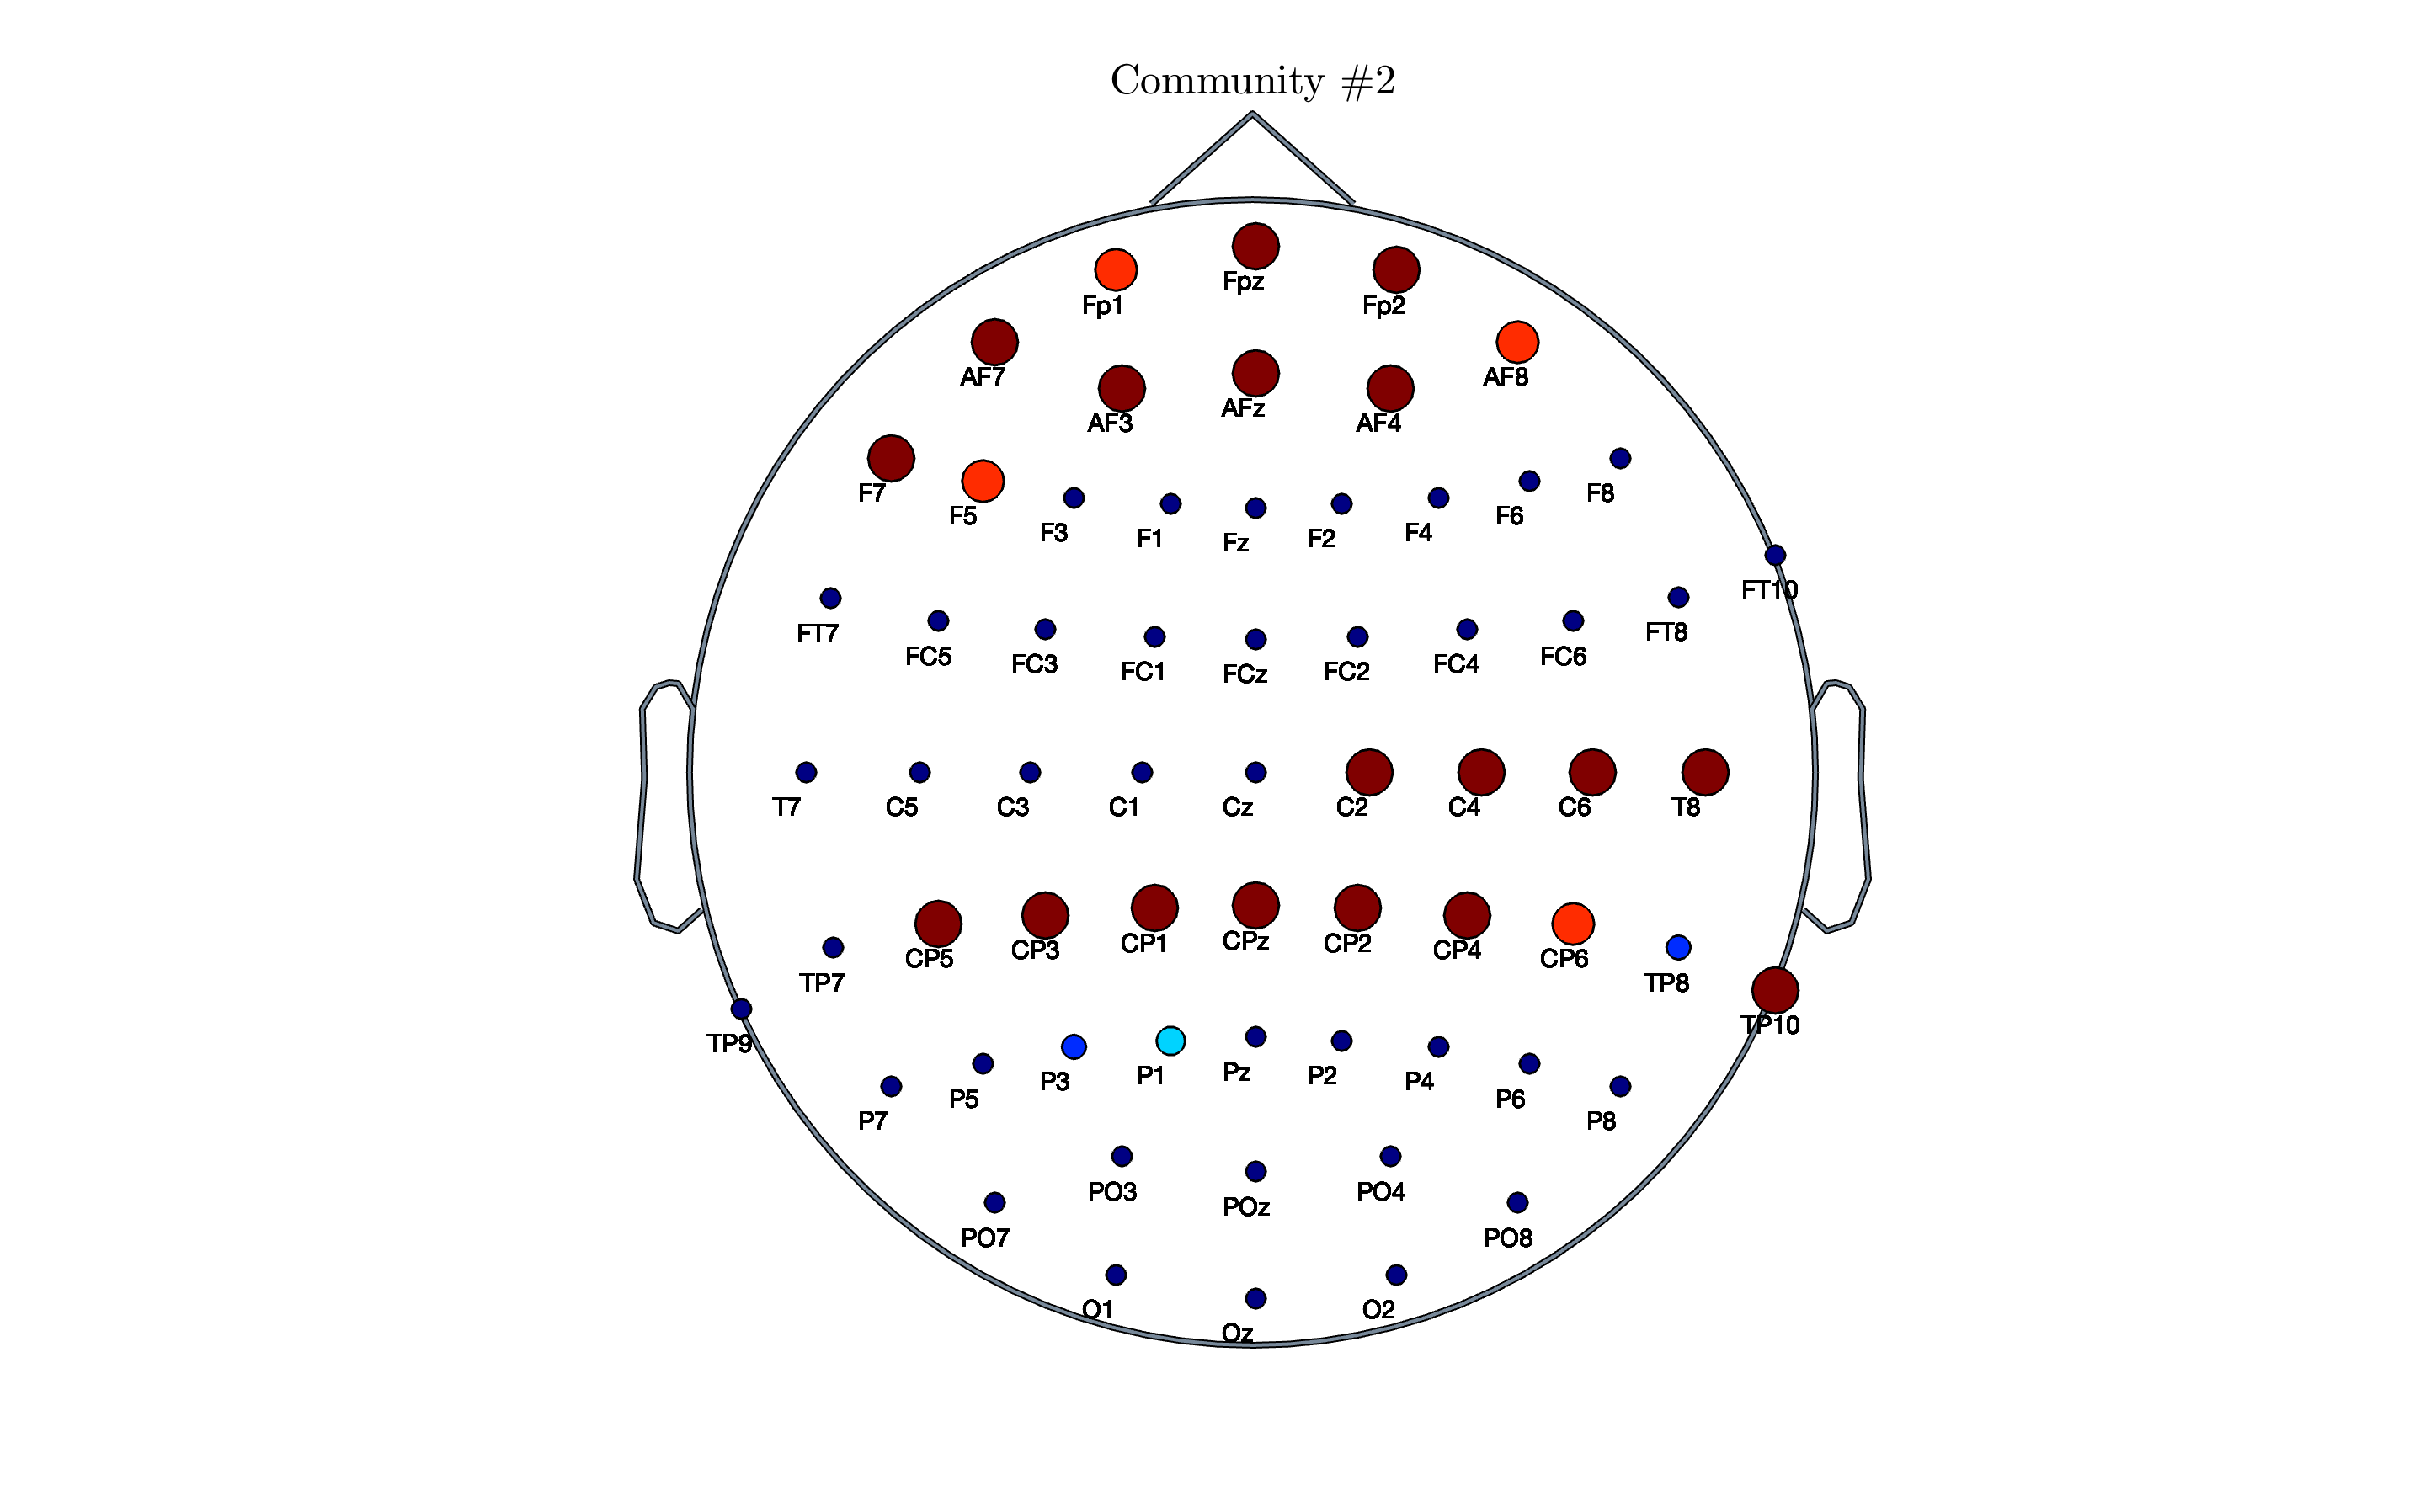


topo_plots = '10-5-System_Mastoids_EGI129.locs';

load("intercluster_strength_data_A09threshold.mat")


aij64 = Al{1};    %64 channels
nch = 64;
ijw = adj2edgeL(triu(aij64));            


for cindex=1:kc
    figure;
    
    if cindex ==3 %Kc outlier removed 
        break
    end

    n_features = prob_of_node_per_cluster{1,cindex}./(length(layers_in_cluster{1,cindex})); % 0<= P < =1
    cbtype = 'nocb';

    figure(cindex)
    title(['Community $\#', num2str(cindex), '$'],'Interpreter','latex' ,'FontSize',25)

    ax = gca;
    ax.TitleFontSizeMultiplier = 3;
    
    f_PlotEEG_BrainNetwork(nch, ijw, 'w_unity', n_features, 'n_nn2nx', cbtype);
end